# Implicit Deep Learning Tutorial on Synthetic Data

The impicit prediction rule reads


$$y=Ax+Bu+c\\
x=\phi(Dx+Eu+f)$$


we consider the well-posedness condition $\|D\|_\infty <1$. We consider the following dimensions $x\in R^h$, $u \in R^n$, $y \in R^p$ with matrices and vectors $A, B, c, D, E, f$ of corresponding appropriate dimensions. 

Let us start by drawing the real weights for the implicit model

n=10; h=100; p=5; density=0.3;
A=sprand(p,h,density).*(sign(rand(p,h)-0.5)); B=sprand(p,n,density).*(sign(rand(p,n)-0.5)); c=rand(p,1)-0.5;
D=sprand(h,h,density).*(sign(rand(h,h)-0.5)); E=sprand(h,n,density).*(sign(rand(h,n)-0.5)); f=rand(h,1)-0.5;
% project D to make it well-posed
funcs=UtilitiesIDL;
D=funcs.infty_norm_projection(D,0.1);

We denote $m$ the number of datapoints, we create our synthetic datatset. We consider that $u \sim \mathcal{N}(0,\Sigma_{\text{train}})$, where $\Sigma_{\text{train}}$ is a covariance matrix

Mat=funcs.RandOrthMat(n); Sigma_train=Mat'*diag(n*rand(n,1))*Mat; clear Mat;
% num of datapoint
m=5*10^2;
U = mvnrnd(zeros(n,1),Sigma_train,m)'; clear Sigma_train;
% find corresponding X using Picard iterations
X=funcs.picard_iterations(U,D,E,f, 'leakyReLU');
Y=A*X+B*U+c*ones(1,m);

## (1) Training Using the Implicit Model

num_iter = 1;
radius = 0.5;
idl=ImplicitDeepLearning(U_train, Y_train, h, num_iter, 0 , radius); idl=idl.train; 

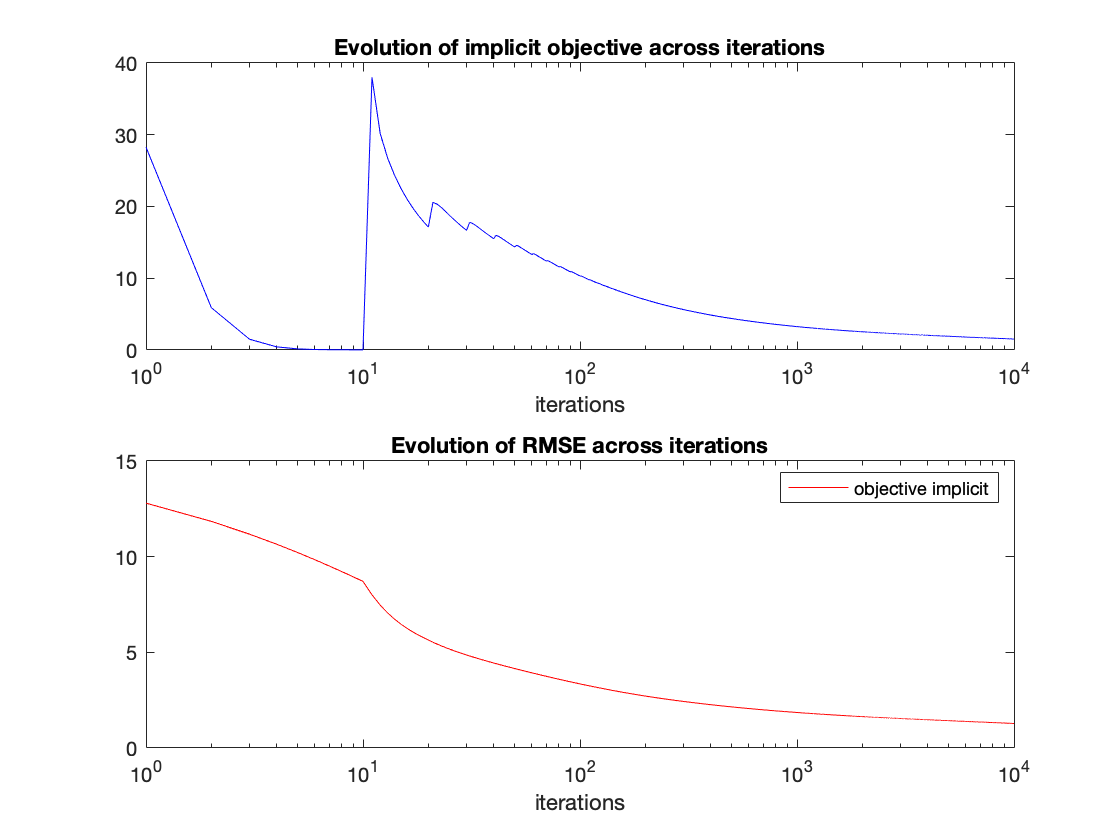

## (2) Linear model fit for comparison

We solve the following convex optimization problem instead (as a comparison)


$$\min_{B_{lin},c_{lin}}\|B_{lin}U+c_{lin}-Y\|_F$$


cvx_begin 
variable B_lin(p,n) 
variable c_lin(p,1)
minimize((1/sqrt(m))*norm(B_lin*U+c_lin*ones(1,m)-Y,'fro'))
cvx_end

 
Calling SDPT3 4.0: 2501 variables, 56 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 56
 dim. of socp   var  = 2501,   num. of socp blk  =  1
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.8e+01|1.4e+00|1.2e+04| 0.000000e+00  0.000000e+00| 0:0:00| chol  1  1 
 1|0.964|1.000|1.7e+00|4.3e-04|5.0e+02|-3.237372e+00 -1.209757e+01| 0:0:00| chol  1  1 
 2|1.000|1.000|9.7e-09|4.3e-05|1.0e+01|-1.546164e+00 -1.159741e+01| 0:0:00| chol  1  1 
 3|1.000|0.889|1.5e-09|8.6e-06|9.0e-01|-3.476636e+00 -4.376

Y_lin=B_lin*U+c_lin*ones(1,m);
disp(['The RMSE for the linear model is: ',num2str(funcs.RMSE(Y,Y_lin))]);

The RMSE for the linear model is: 4.1857


## (3) Neural Network Prediction rule for comparison

We fit a feedforward neural network model with 3 hidden layers of width $h$ (i.e. the total dimension of the hidden layer is $3h$ )

layers = [
    sequenceInputLayer(n)
    fullyConnectedLayer(h/2)
    reluLayer 
    fullyConnectedLayer(h/2)
    reluLayer
    fullyConnectedLayer(h/2)
    reluLayer
    fullyConnectedLayer(p)
    regressionLayer];

options = trainingOptions('rmsprop','MaxEpochs',10^3,'MiniBatchSize',m,'InitialLearnRate',10^-3);
net = trainNetwork(U,Y,layers,options);

Training on single CPU.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:00 |        10.29 |         52.9 |          0.0010 |
|      50 |          50 |       00:00:00 |         4.30 |          9.2 |          0.0010 |
|     100 |         100 |       00:00:01 |         2.50 |          3.1 |          0.0010 |
|     150 |         150 |       00:00:01 |         1.99 |          2.0 |          0.0010 |
|     200 |         200 |       00:00:02 |         1.83 |          1.7 |          0.0010 |
|     250 |         250 |       00:00:02 |         1.56 |          1.2 |          0.0010 |
|     300 |         300 |       00:00:03 |         1.46 |         

## Random functions

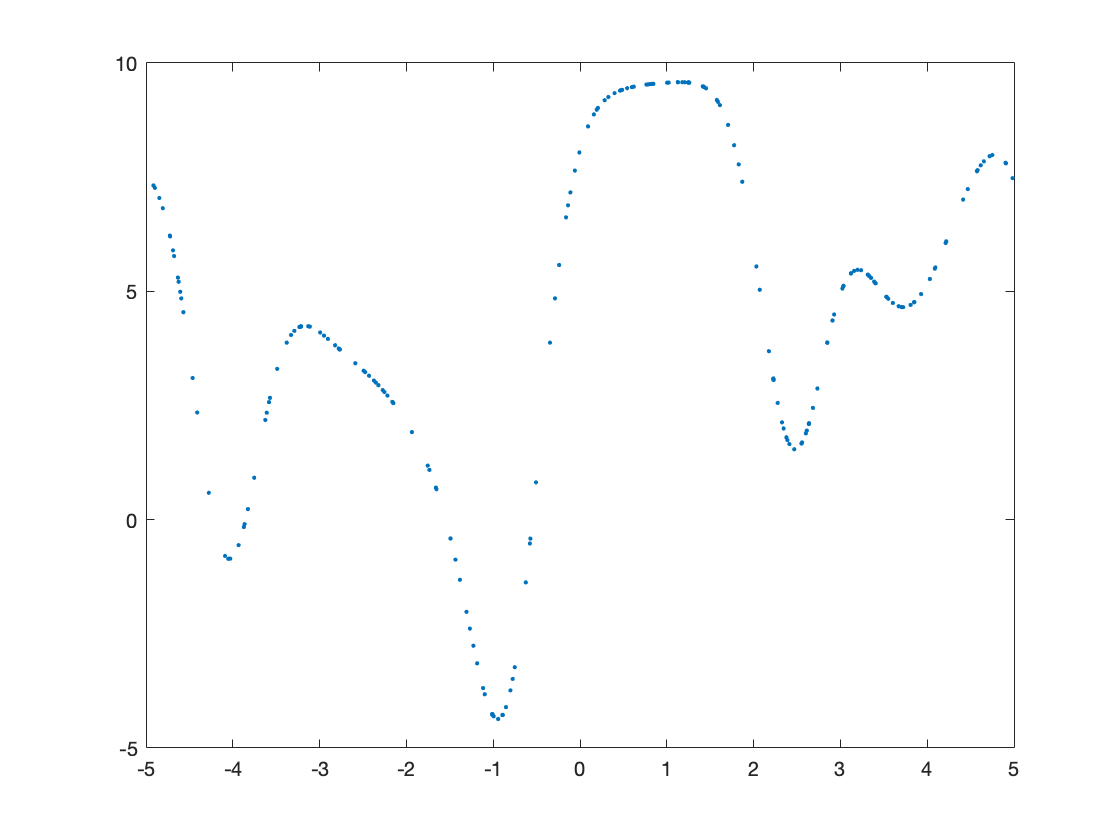

m =200;
num = 10;
alpha =2*(rand(num,1));
U_train = 10*(rand(1,m)-0.5);
Y_train = NaN* zeros(1,m);
for k =1:m
    Y_train(k) = 0;
    for i = 1:num
        Y_train(k) = Y_train(k)+alpha(i)*(sin(alpha(i)*U_train(k)+cos(alpha(i)*U_train(k)))); 
    end
end
figure()
plot(U_train, Y_train, '.');

tic
h = 100;
num_iter = 2;
radius = 0.5;
idl=ImplicitDeepLearning(U_train, Y_train, h, num_iter, 0 , radius); idl=idl.train; 
disp(toc)

    0.0539



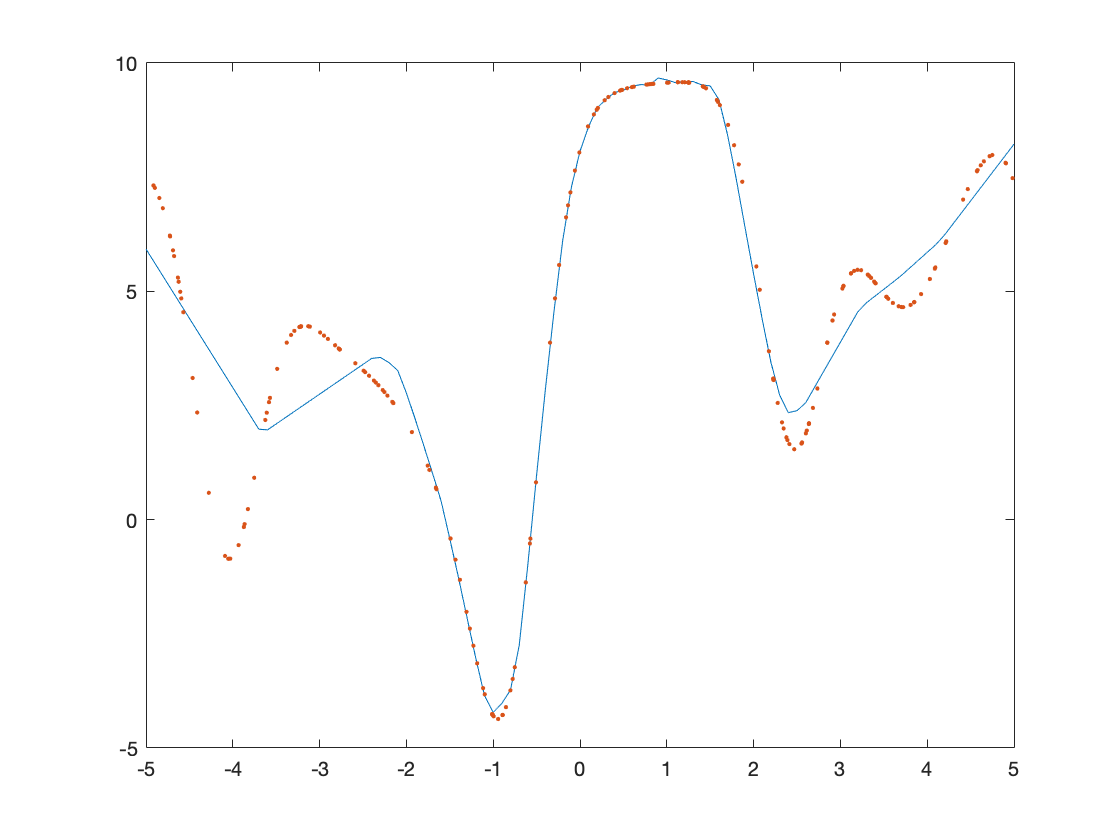

U = -5:0.1:5;
Y_prediction = idl.implicit_prediction(U);
figure()
plot(U, Y_prediction, '-')
hold on
plot(U_train, Y_train, '.');

tic
n = ceil(h/4);
layers = [
    sequenceInputLayer(1)
    fullyConnectedLayer(n)
    reluLayer 
    fullyConnectedLayer(n)
    reluLayer
    fullyConnectedLayer(n)
    reluLayer
    fullyConnectedLayer(n)
    reluLayer
    fullyConnectedLayer(1)
    regressionLayer];

options = trainingOptions('rmsprop','MaxEpochs',10^3,'MiniBatchSize',m,'InitialLearnRate',10^-3);
net = trainNetwork(U_train,Y_train,layers,options);

Training on single CPU.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:00 |         5.87 |         17.2 |          0.0010 |
|      50 |          50 |       00:00:00 |         3.86 |          7.4 |          0.0010 |
|     100 |         100 |       00:00:01 |         3.36 |          5.7 |          0.0010 |
|     150 |         150 |       00:00:02 |         2.54 |          3.2 |          0.0010 |
|     200 |         200 |       00:00:02 |         2.01 |          2.0 |          0.0010 |
|     250 |         250 |       00:00:03 |         1.85 |          1.7 |          0.0010 |
|     300 |         300 |       00:00:04 |         1.77 |         

disp(toc)

   14.8146



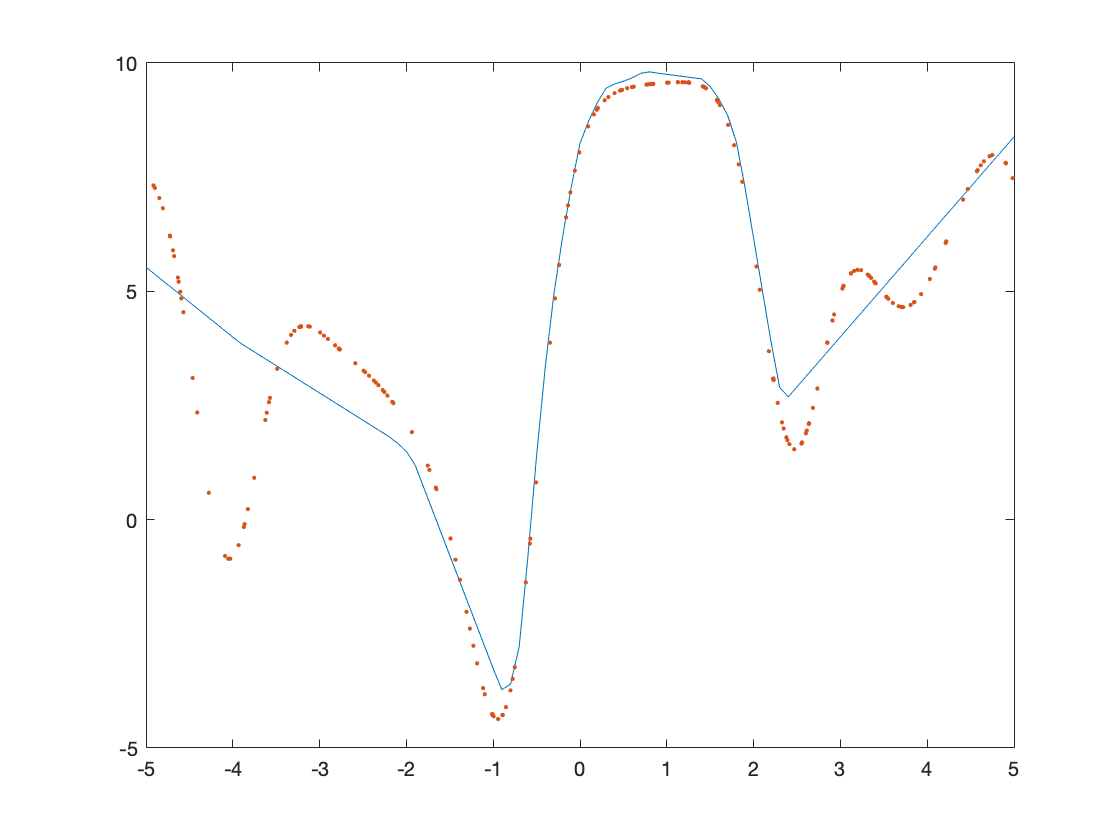

Y_prediction = predict(net,U);
figure()
plot(U, Y_prediction, '-')
hold on
plot(U_train, Y_train, '.');